# Plot

UWCC Structural Analysis: Heerod Sahraei

Run after Main.mlx

## Moment and Shear

### Inputs

toPlot = ["RaceStands", "MaleTandem","FemaleTandem",];
displayName = ["Race Stands", "MaleTandem","FemaleTandem"];
colors = ["red","blue","green"];

### Diagrams

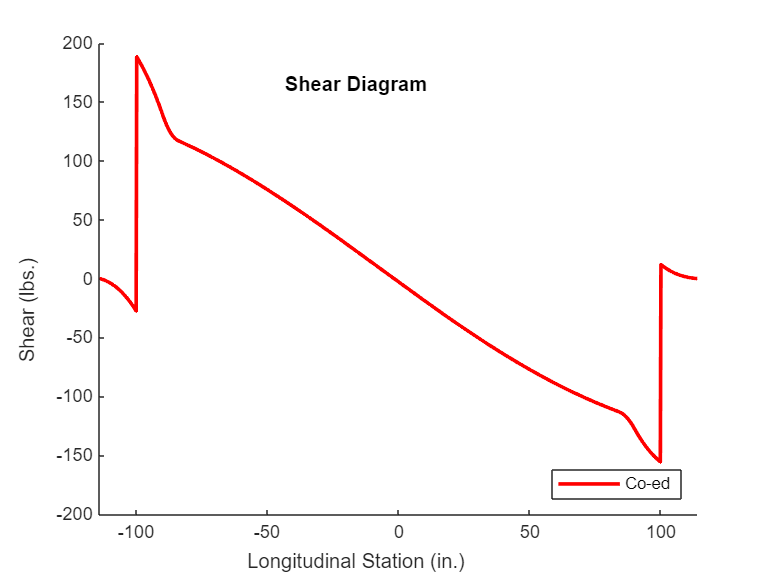

close all;

for i = 1:numel(toPlot)
    V = LoadCases.(toPlot(i)).ShearDistribution;
    hold on
    plot(xInterp,V,'Color',colors(i),'LineWidth',2,'DisplayName',displayName(i));
    xlim([xInterp(1) xInterp(end)]);
    title('Shear Diagram');
    xlabel('Longitudinal Station (in.)');
    ylabel('Shear (lbs.)');
    legend("Location","southeast");
end

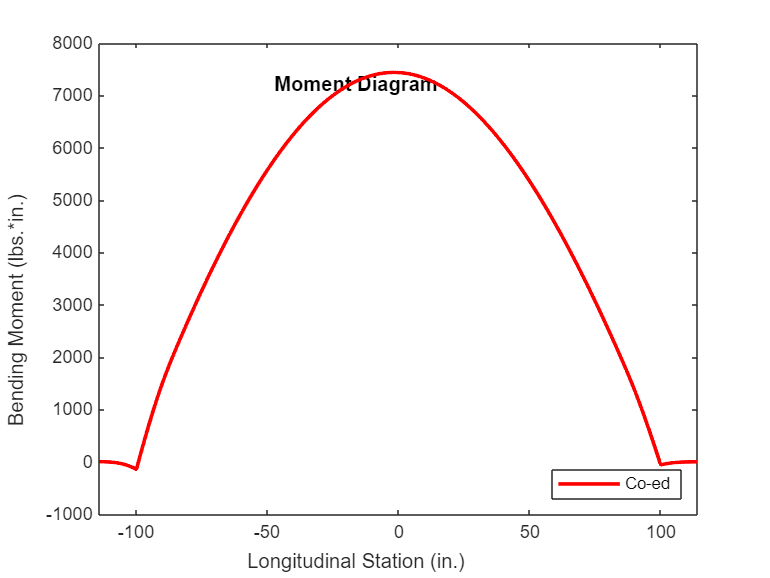


figure;
for i = 1:numel(toPlot)
    M = LoadCases.(toPlot(i)).MomentDistribution;
    hold on
    plot(xInterp,M,'Color', colors(i), 'LineWidth', 2, 'DisplayName',displayName(i));
    xlim([xInterp(1) xInterp(end)]);
    title('Moment Diagram');
    xlabel('Longitudinal Station (in.)');
    ylabel('Bending Moment (lbs.*in.)');
    legend("Location","southeast");
    
end

## Cable Force Envelope